# Exercise 1: Prepare dataset from Time-of-Flight (ToF) sensor

This exercise shows how to view, process and interpret the data acquired from the VL53L8CX senor from ST Microelectronics. You will use the logged sensor data in a tabular format and augmented with different rotations and flips. 

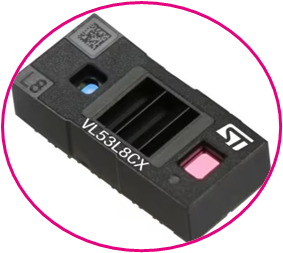

## Load logged sensor data

Load dataset as table that contain ToFReading, ZonalData and Gesture classifications. 

load("dataTable_4Class.mat"); 
% Display selected rows in the table
disp(dataTable([1 3000 end], :)); 

     ToFReading      ZonalData       Gesture 
    ____________    ____________    _________

    {8×8 double}    {8×8 double}    BreakTime
    {8×8 double}    {8×8 double}    FlatHand 
    {8×8 double}    {8×8 double}    Love     



% set up classes of interests
classNames = categories(dataTable{:,"Gesture"}); 

## Display sample data 

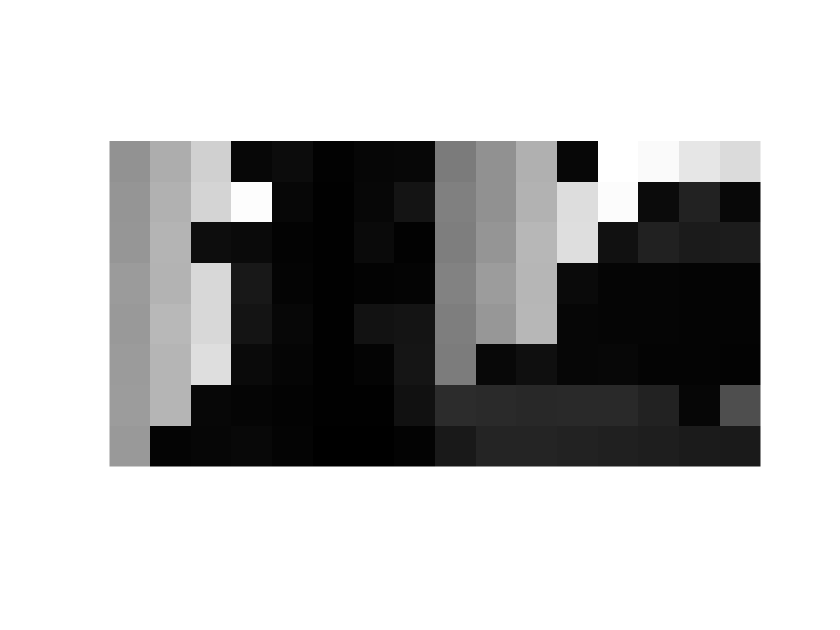

breaktime_1 = dataTable(1,:); 
flathand_1 = dataTable(3000, :);
love_1 = dataTable(end, :);
imgT_tof = imtile({breaktime_1.ToFReading{1}, flathand_1.ToFReading{1}}); 
imshow(imgT_tof, [], InitialMagnification="fit"); 

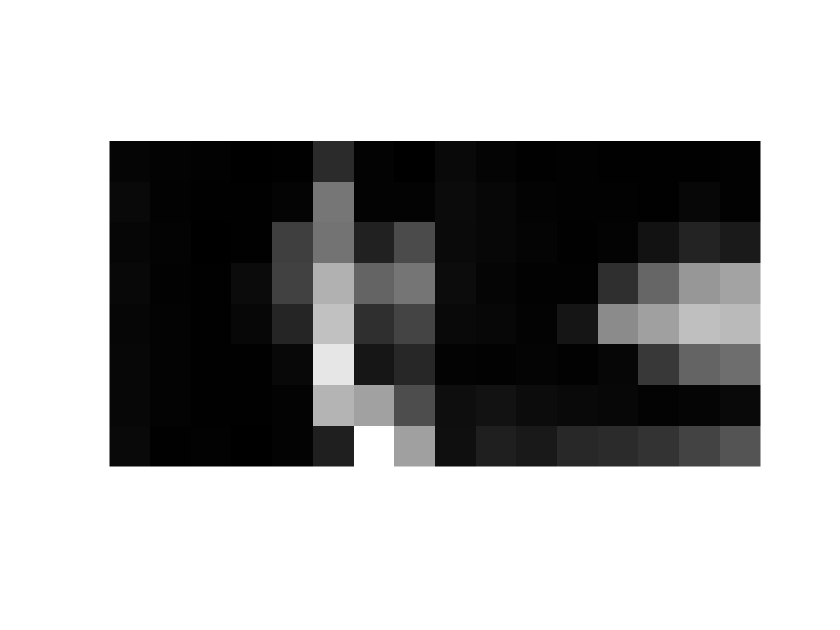

imgT_zone = imtile({breaktime_1.ZonalData{1}, flathand_1.ZonalData{1}}); 
imshow(imgT_zone, [], InitialMagnification="fit"); 

## Augment data with rotations and flips

An image data augmenter configures a set of preprocessing options for image augmentation, such as resizing, rotation, and reflection.

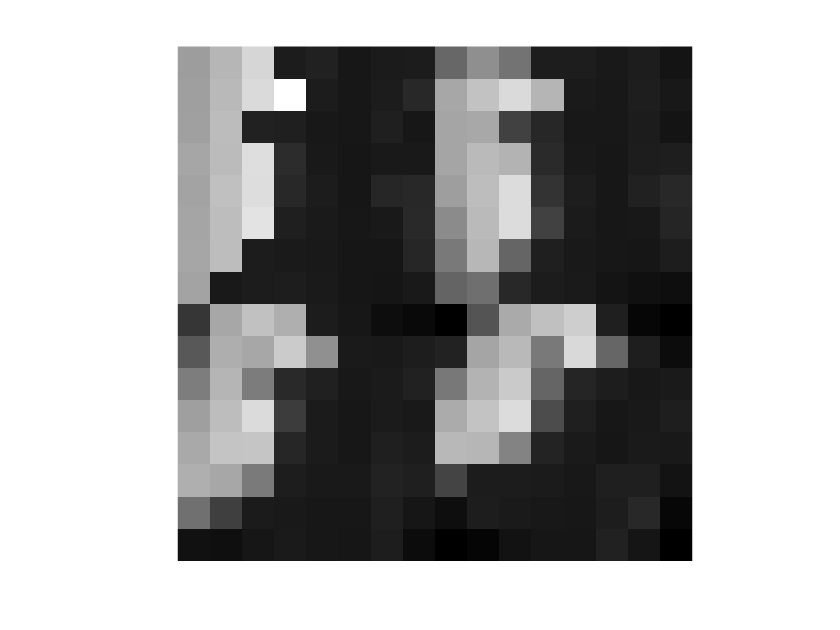

imageAugmenter = imageDataAugmenter( ...
    'RandRotation',[-90,90]); 

rotate1 = augment(imageAugmenter,{breaktime_1.ToFReading{1}});
rotate2 = augment(imageAugmenter,{breaktime_1.ToFReading{1}});
rotate3 = augment(imageAugmenter,{breaktime_1.ToFReading{1}});
imgAug_tof = imtile([breaktime_1.ToFReading{1}, rotate1, rotate2, rotate3]);
imshow(imgAug_tof, [], InitialMagnification="fit", Border="loose"); 

## Perform the data augmentation on all the data

Bring out the training portion of the data and rotate with random angle. 

imageSize = [8 8 1];
[xTrain, label_Train, ~, ~] = trainWithTabularData(dataTable);
% Use augmentedImageDatastore object for training
augimds = augmentedImageDatastore(imageSize,xTrain,label_Train,'DataAugmentation',imageAugmenter)

augimds =   augmentedImageDatastore with properties:

         NumObservations: 4248
           MiniBatchSize: 128
        DataAugmentation: [1×1 imageDataAugmenter]
      ColorPreprocessing: 'none'
              OutputSize: [8 8]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


## Save the original data and augmented data

% Save as new dataset
save("dataAugmented.mat");  %name the new variables